% Download the SpeakerDiarization.zip file and store it in downloadFolder
downloadFolder = matlab.internal.examples.downloadSupportFile("audio","SpeakerDiarization.zip");

% Set the dataFolder to the system temporary directory
dataFolder = tempdir;

% Unzip the downloaded file into the dataFolder
unzip(downloadFolder, dataFolder)

% Set the netFolder to the SpeakerDiarization subfolder inside dataFolder
netFolder = fullfile(dataFolder, "SpeakerDiarization");

% Add the netFolder to the MATLAB path
addpath(netFolder)

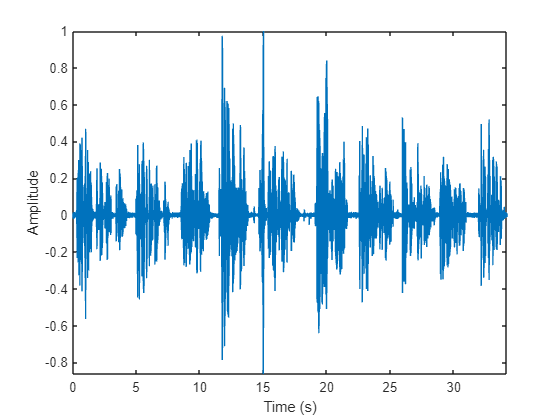

% Read audio data and sampling rate from the exampleconversation.flac file
[audioIn, fs] = audioread("exampleconversation.flac");

% Load speaker labels from the exampleconversationlabels.mat file
load("exampleconversationlabels.mat")

% Normalize audio to have maximum amplitude of 1
audioIn = audioIn ./ max(abs(audioIn));

% Play the audio
sound(audioIn, fs)

% Generate time vector based on audio length and sampling rate
t = (0:size(audioIn, 1) - 1) / fs;

% Plot the audio waveform over time
figure(1)
plot(t, audioIn)
xlabel("Time (s)")
ylabel("Amplitude")
axis tight  % Adjust the axes limits to fit the data

% Load the MATLAB structure from the "xvectorSystem.mat" file
xvecsys = load("xvectorSystem.mat");

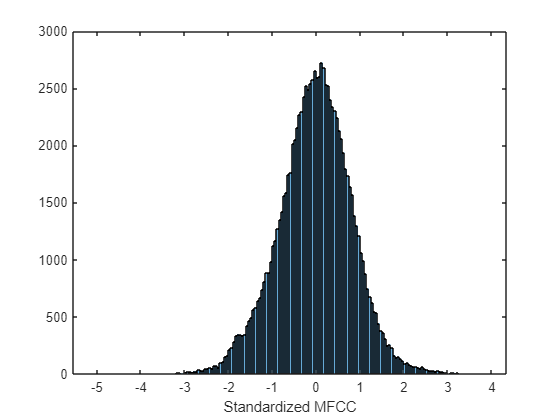

% Extract features using the model stored in the 'xvecsys' structure
% 'extract' is assumed to be a function that extracts features from 'audioIn' using 'xvecsys.afe' (assuming 'afe' is a field in 'xvecsys')
% The extracted features are then standardized using the mean and standard deviation factors stored in 'xvecsys.factors.Mean' and 'xvecsys.factors.STD'
features = single((extract(xvecsys.afe, audioIn) - xvecsys.factors.Mean') ./ xvecsys.factors.STD');

% Plot a histogram of the standardized features
figure(2)
histogram(features)
xlabel("Standardized MFCC")

% Compute the duration of each feature vector in seconds
featureVectorHopDur = (numel(xvecsys.afe.Window) - xvecsys.afe.OverlapLength) / xvecsys.afe.SampleRate;

% Specify the duration and hop duration of each segment in seconds
segmentDur = 2;
segmentHopDur = 0.1;

% Calculate the number of feature vectors in each segment
segmentLength = round(segmentDur / featureVectorHopDur);

% Calculate the number of feature vectors to hop between segments
segmentHop = round(segmentHopDur / featureVectorHopDur);

% Initialize an index vector for segmenting features
idx = 1:segmentLength;

% Initialize an empty array to store segmented features
featuresSegmented = [];

% Iterate over the entire feature set to segment features
while idx(end) < size(features, 1)
    % Extract features for the current segment and concatenate them along the third dimension
    featuresSegmented = cat(3, featuresSegmented, features(idx, :));
    
    % Update the index vector to hop to the next segment
    idx = idx + segmentHop;
end

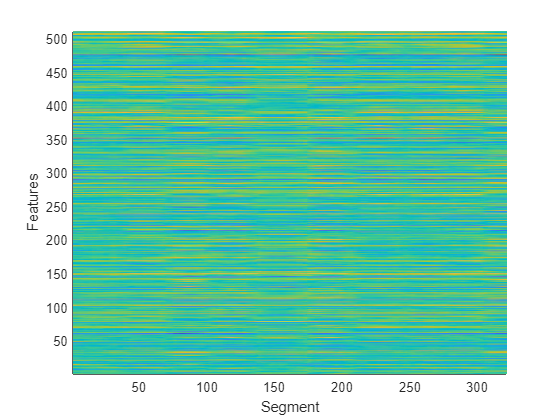

% Initialize a matrix to store the embeddings for each segment
xvecs = zeros(512, size(featuresSegmented, 3));

% Iterate over each segment of segmented features
for sample = 1:size(featuresSegmented, 3)
    % Convert the segmented features to a deep learning array (dlarray)
    dlX = dlarray(featuresSegmented(:, :, sample), "TCB");
    
    % Use the deep learning model to predict embeddings for the segment
    % The 'predict' function computes embeddings using 'xvecsys.dlnet' model and 'fc_1' output layer
    xvecs(:, sample) = predict(xvecsys.dlnet, dlX, Outputs="fc_1");
end

% Plot the embeddings as a surface plot
figure(3)
surf(xvecs', EdgeColor="none")

% Set the view angle for the plot
view([90, -90])

% Set the axis limits based on the dimensions of the embeddings
axis([1 size(xvecs, 1) 1 size(xvecs, 2)])

% Set labels for the axes
xlabel("Features")
ylabel("Segment")

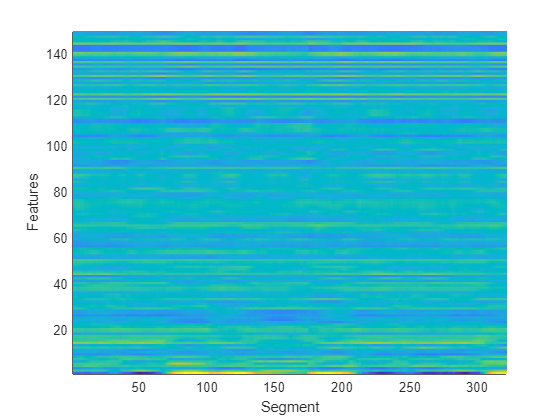

% Perform matrix multiplication between the projection matrix and embeddings
x = xvecsys.projMat * xvecs;

% Plot the result as a surface plot
figure(4)
surf(x', EdgeColor="none")

% Set the view angle for the plot
view([90, -90])

% Set the axis limits based on the dimensions of the result matrix
axis([1 size(x, 1) 1 size(x, 2)])

% Set labels for the axes
xlabel("Features")
ylabel("Segment")

% Determine the number of known speakers from ground truth labels
knownNumberOfSpeakers = numel(unique(groundTruth.Label));

% Set the maximum number of clusters to knownNumberOfSpeakers + 1
maxclusters = knownNumberOfSpeakers + 1;

% Specify the clustering method
clusterMethod = 'agglomerative - PLDA scoring';

% Perform clustering based on the specified method
switch clusterMethod
    case "agglomerative - PLDA scoring"
        % Cluster data using agglomerative clustering with PLDA scoring
        % The 'helperPLDAScorer' function computes distances based on PLDA scores
        T = clusterdata(x', Criterion="distance", distance=@(a,b)helperPLDAScorer(a,b,xvecsys.plda), linkage="average", maxclust=maxclusters);
        
    case "agglomerative - CSS scoring"
        % Cluster data using agglomerative clustering with cosine similarity scoring
        T = clusterdata(x', Criterion="distance", distance="cosine", linkage="average", maxclust=maxclusters);
        
    case "kmeans - CSS scoring"
        % Cluster data using k-means clustering with cosine similarity scoring
        T = kmeans(x', maxclusters, Distance="cosine");
end

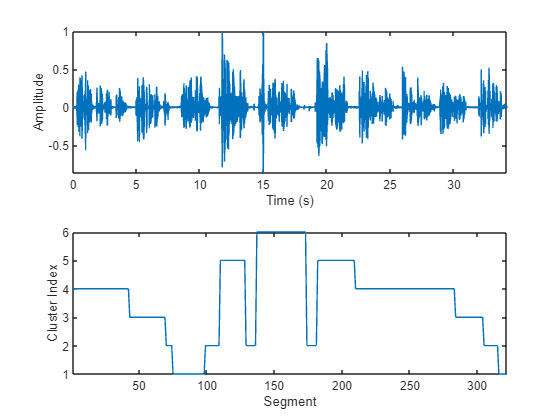

% Create a new figure with a 2x1 tiled layout
figure(5)
tiledlayout(2, 1)

% Plot the audio waveform in the first subplot
nexttile
plot(t, audioIn)
axis tight
ylabel("Amplitude")
xlabel("Time (s)")

% Plot the cluster index over time in the second subplot
nexttile
plot(T)
axis tight
ylabel("Cluster Index")
xlabel("Segment")

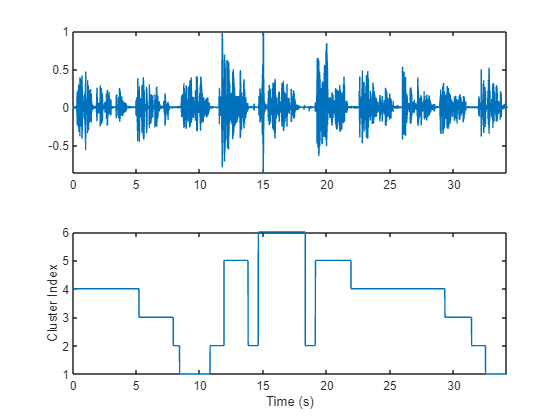

% Initialize the mask with zeros
mask = zeros(size(audioIn, 1), 1);

% Calculate the index where the first segment starts
start = round((segmentDur / 2) * fs);

% Calculate the number of samples between segment hops
segmentHopSamples = round(segmentHopDur * fs);

% Assign cluster indices to samples in the mask
mask(1:start) = T(1);
start = start + 1;
for ii = 1:numel(T)
    finish = start + segmentHopSamples;
    mask(start:start + segmentHopSamples) = T(ii);
    start = finish + 1;
end
mask(finish:end) = T(end);

% Create a new figure with a 2x1 tiled layout
figure(6)
tiledlayout(2, 1)

% Plot the audio waveform in the first subplot
nexttile
plot(t, audioIn)
axis tight

% Plot the cluster index mask over time in the second subplot
nexttile
plot(t, mask)
ylabel("Cluster Index")
axis tight
xlabel("Time (s)")

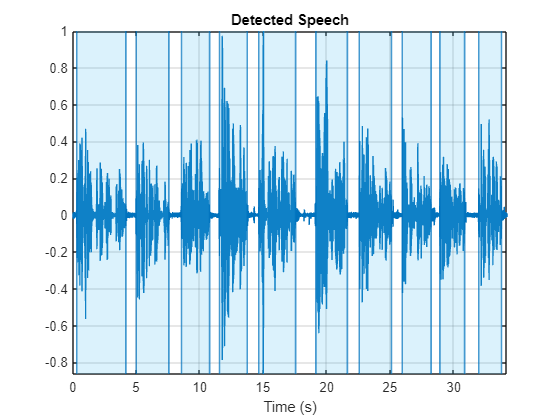

% Set the merge duration for voice activity detection
mergeDuration = 0.5;

% Perform voice activity detection on the audio signal
VADidx = detectSpeech(audioIn, fs, MergeDistance=fs * mergeDuration);

% Generate a binary mask based on the detected speech segments
VADmask = sigroi2binmask(VADidx, numel(audioIn));

% Visualize the detected speech segments
figure(7)
detectSpeech(audioIn, fs, MergeDistance=fs * mergeDuration)

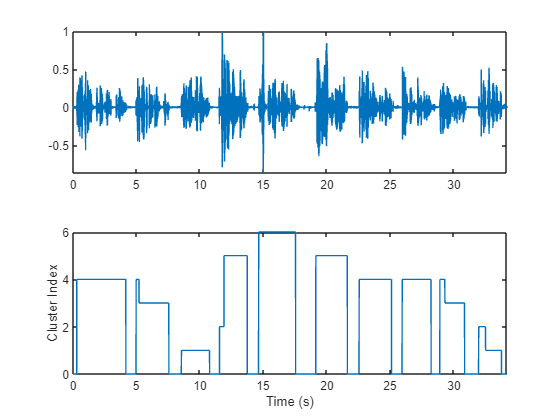

%Apply the VAD mask to the speaker mask and plot the results. A cluster index of 0 indicates a region of no speech.
mask = mask.*VADmask;

figure(8)
tiledlayout(2,1)

nexttile
plot(t,audioIn)
axis tight

nexttile
plot(t,mask)
ylabel("Cluster Index")
axis tight
xlabel("Time (s)")

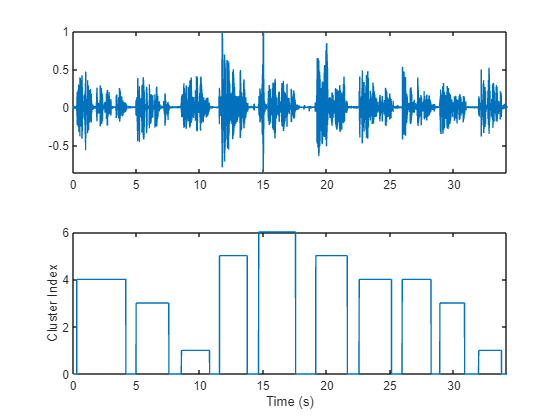

% Initialize an array to store the mask labels for each VAD segment
maskLabels = zeros(size(VADidx, 1), 1);

% Iterate over each VAD segment
for ii = 1:size(VADidx, 1)
    % Compute the mode of the original mask within the VAD segment
    maskLabels(ii) = mode(mask(VADidx(ii, 1):VADidx(ii, 2)), "all");
    
    % Assign the mode label to the original mask within the VAD segment
    mask(VADidx(ii, 1):VADidx(ii, 2)) = maskLabels(ii);
end

% Create a new figure with a 2x1 tiled layout
figure(9)
tiledlayout(2, 1)

% Plot the audio waveform in the first subplot
nexttile
plot(t, audioIn)
axis tight

% Plot the mask with cluster indices in the second subplot
nexttile
plot(t, mask)
ylabel("Cluster Index")
axis tight
xlabel("Time (s)")

% Get unique speaker clusters and the number of speakers
uniqueSpeakerClusters = unique(maskLabels);
numSpeakers = numel(uniqueSpeakerClusters);

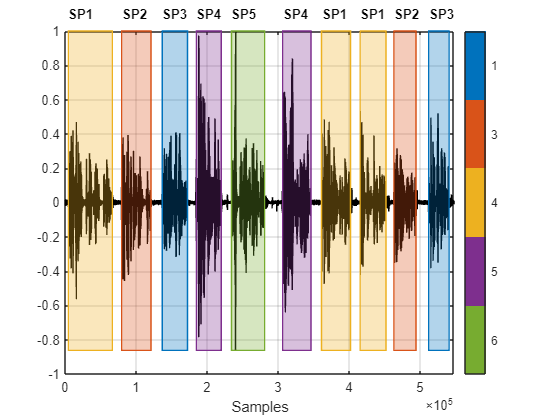

% Generate a signal mask from the VAD segments and cluster labels
msk = signalMask(table(VADidx, categorical(maskLabels)));

% Plot the signal mask along with the audio waveform
figure(10)
plotsigroi(msk, audioIn, true)
axis([0 numel(audioIn) -1 1])

% Add ground truth labels as text annotations
trueLabel = groundTruth.Label;
for ii = 1:numel(trueLabel)  
    text(VADidx(ii, 1), 1.1, trueLabel(ii), FontWeight="bold")
end

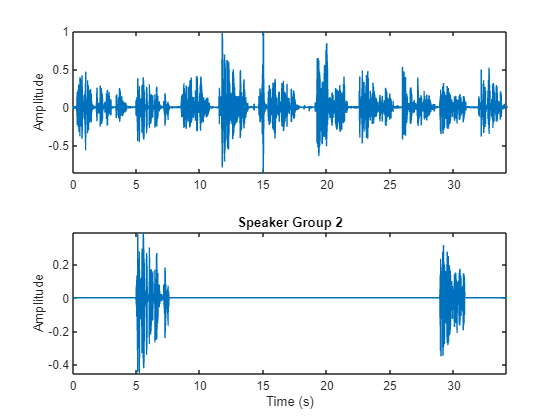

speakerToInspect = 2;
cutOutSilenceFromAudio = true;

bmsk = binmask(msk,numel(audioIn));

audioToPlay = audioIn;
if cutOutSilenceFromAudio
    audioToPlay(~bmsk(:,speakerToInspect)) = [];
end
sound(audioToPlay,fs)

figure(11)
tiledlayout(2,1)

nexttile
plot(t,audioIn)
axis tight
ylabel("Amplitude")

nexttile
plot(t,audioIn.*bmsk(:,speakerToInspect))
axis tight
xlabel("Time (s)")
ylabel("Amplitude")
title("Speaker Group "+speakerToInspect)

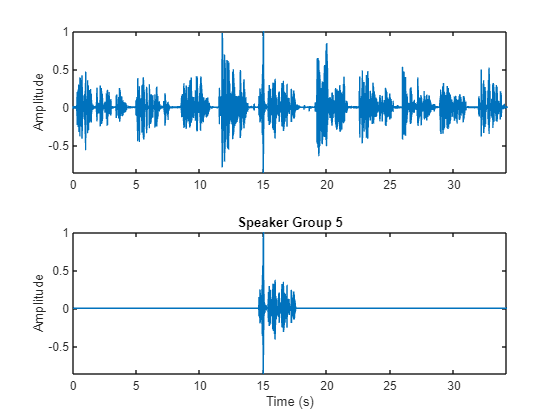

speakerToInspect = 5;
cutOutSilenceFromAudio = true;

bmsk = binmask(msk,numel(audioIn));

audioToPlay = audioIn;
if cutOutSilenceFromAudio
    audioToPlay(~bmsk(:,speakerToInspect)) = [];
end
sound(audioToPlay,fs)

figure(11)
tiledlayout(2,1)

nexttile
plot(t,audioIn)
axis tight
ylabel("Amplitude")

nexttile
plot(t,audioIn.*bmsk(:,speakerToInspect))
axis tight
xlabel("Time (s)")
ylabel("Amplitude")
title("Speaker Group "+speakerToInspect)

% Get unique labels from the ground truth
uniqueLabels = unique(trueLabel);

% Initialize variables to store the total number of errors and unique guess labels
totalNumErrors = 0;
uniqueGuessLabels = unique(maskLabels);

% Iterate over each unique label in the ground truth
for ii = 1:numel(uniqueLabels)
    % Determine which instances belong to the current speaker
    isSpeaker = uniqueLabels(ii) == trueLabel;
    
    % Initialize variables to store the minimum number of errors and the best candidate
    minNumErrors = inf;
    
    % Iterate over each unique guess label
    for jj = 1:numel(uniqueGuessLabels)
        % Determine which instances belong to the current guess label
        groupCandidate = uniqueGuessLabels(jj) == maskLabels;
        
        % Calculate the number of errors by comparing the speaker group with the guess group
        numErrors = nnz(isSpeaker - groupCandidate);
        
        % Update the minimum number of errors and the best candidate
        if numErrors < minNumErrors
            minNumErrors = numErrors;
            bestCandidate = jj;
        end
    end
    
    % Update the total number of errors and remove the best candidate from the unique guess labels
    totalNumErrors = totalNumErrors + minNumErrors;
    uniqueGuessLabels(bestCandidate) = [];
    
    % Exit the loop if all guess labels have been exhausted
    if isempty(uniqueGuessLabels)
        break
    end
end

% Calculate the speaker error rate
SpeakerErrorRate = totalNumErrors / numel(trueLabel);
